# Support structure cost - Live script

- Imports sea depth (bathymetry) data

- Sets turbines to random posittions

- Calculates the water depth at each point

- Uses design variables for depths ranges each support type is used in to set support type for each turbine

- Calcuates the cost of support for each turbine 

% importing bathymetry data, setting random turbine coordinates, and
% calculating water depth at each point
[A,R] = readgeoraster('hsb.tif','OutputType','double');
latlim = R.LatitudeLimits;
longlim = R.LongitudeLimits;

info = geotiffinfo('hsb.tif');
height = info.Height; % Integer indicating the height of the image in pixels
width = info.Width; % Integer indicating the width of the image in pixels
x = 1:width;
y = 1:height;

max_lat = 54; 
min_lat = 53.7; 
max_long = 2.8; 
min_long = 2.1;

TCA = zeros([300,4]);%main turbine cost array 

for t=1:300 %for turbine 1 - turbine 300
    
    % set y/longtitude coord 
    TCA(t,2)= min_long + (max_long-min_long).*rand();
    
    % set x/latitide coord
    TCA(t,1)= min_lat + (max_lat-min_lat).*rand();
    
end

TCA

TCA =    53.7429    2.7800         0         0
   53.9286    2.6998         0         0
   53.8378    2.6322         0         0
   53.7322    2.3689         0         0
   53.7442    2.4188         0         0
   53.8141    2.3055         0         0
   53.7580    2.7472         0         0
   53.8183    2.5585         0         0
   53.7095    2.2354         0         0
   53.7940    2.6613         0         0


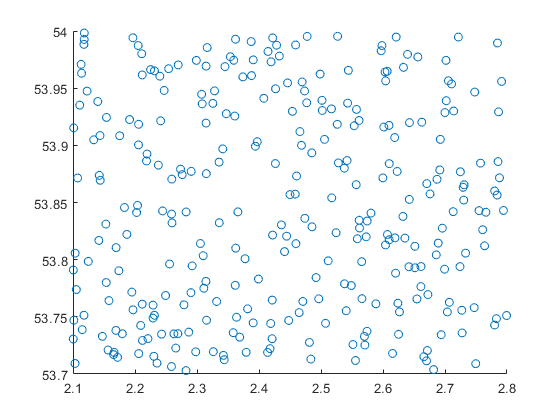

scatter(TCA(:,2),TCA(:,1))


[rows,cols] = meshgrid(1:height,1:width);
[ADlat,ADlon] = pix2latlon(info.RefMatrix, rows, cols);
Idub=A;
% Interpolate meshgrid of bathymetry data to get water depths at each
% turbine location
TCA(:,3) = interp2(ADlat, ADlon, Idub.', TCA(:,1), TCA(:,2)) % X, Y (not in same order as lat long btw)

TCA =    53.7429    2.7800  -33.7063         0
   53.9286    2.6998  -38.3677         0
   53.8378    2.6322  -69.4486         0
   53.7322    2.3689  -29.0000         0
   53.7442    2.4188  -29.9827         0
   53.8141    2.3055  -32.0000         0
   53.7580    2.7472  -33.0000         0
   53.8183    2.5585  -31.9366         0
   53.7095    2.2354  -28.7849         0
   53.7940    2.6613  -31.0122         0


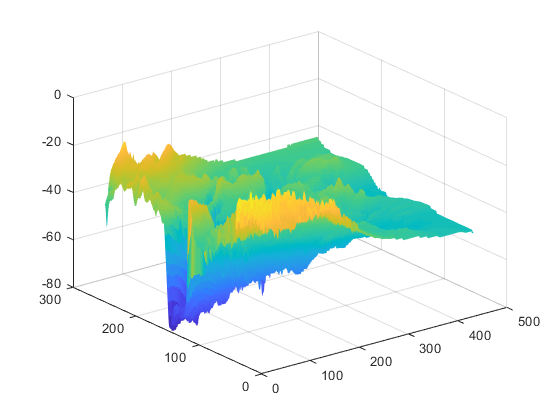

surf(Idub, 'edgecolor', 'none'); colormap(parula(256))

then needs to calculate support structure cost - dependant on water depth 

%"design variables" to optimise each loop = cut off depths for what support
%structure used. no over lap beween depths at which each support type is
%used
mp_limit_var = -30; 
j_limit_var = -80;  %number regarding to sea depth

%split TCA based on depth values, to get seperate arrays of depths for
%different turbine types
mp_tca = TCA(TCA(:,3)>=mp_limit_var,:) 

mp_tca =    53.7322    2.3689  -29.0000         0
   53.7442    2.4188  -29.9827         0
   53.7095    2.2354  -28.7849         0
   53.8665    2.6706  -28.0791         0
   53.7985    2.1246  -24.0000         0
   53.7118    2.5557  -29.0000         0
   53.7739    2.1053  -28.7718         0
   53.7843    2.4921  -28.8453         0
   53.7366    2.2867  -30.0000         0
   53.7188    2.4139  -29.0000         0


j_tca = TCA(TCA(:,3)>=j_limit_var,:) 

j_tca =    53.7429    2.7800  -33.7063         0
   53.9286    2.6998  -38.3677         0
   53.8378    2.6322  -69.4486         0
   53.7322    2.3689  -29.0000         0
   53.7442    2.4188  -29.9827         0
   53.8141    2.3055  -32.0000         0
   53.7580    2.7472  -33.0000         0
   53.8183    2.5585  -31.9366         0
   53.7095    2.2354  -28.7849         0
   53.7940    2.6613  -31.0122         0



%cost of support types - from minimalistic cost model 
gp = 6; %installed generator power in MW (6MW used on site)
c_t = 1.25*(-0.15+0.92*gp); %cost of wind turbine

%support structure cost equations (for reference, not used in code)
d = 25; %water depth in m
c_mp = (gp*(d*d +100*d +1500))/7500; %monopile
c_j = (gp*(0.5*(d*d)-35*d+2500))/7500; %jacket support structure

mpd = abs(mp_tca(:,3)); %monopile depth
mp_tca(:,4) = (gp*(mpd.^2 +100*mpd +1500))/7500; % cost of monopile support in million euros

%total monopile turbine support costs
tot_mp = sum(mp_tca(:,4),"all");

jd = abs(j_tca(:,3)); %jacket depth
j_tca(:,4) = (gp*(0.5*(jd.^2)-35*jd+2500))/7500 %jacket support structure in million euros

j_tca =    53.7429    2.7800  -33.7063    1.5107
   53.9286    2.6998  -38.3677    1.5145
   53.8378    2.6322  -69.4486    1.9847
   53.7322    2.3689  -29.0000    1.5244
   53.7442    2.4188  -29.9827    1.5201
   53.8141    2.3055  -32.0000    1.5136
   53.7580    2.7472  -33.0000    1.5116
   53.8183    2.5585  -31.9366    1.5138
   53.7095    2.2354  -28.7849    1.5255
   53.7940    2.6613  -31.0122    1.5164



% total jacket turbine support cost
tot_j = sum(j_tca(:,4),"all");


%  Total support structure cost (in million euros)
tot_support_cost = tot_mp + tot_j

tot_support_cost = 773.1067